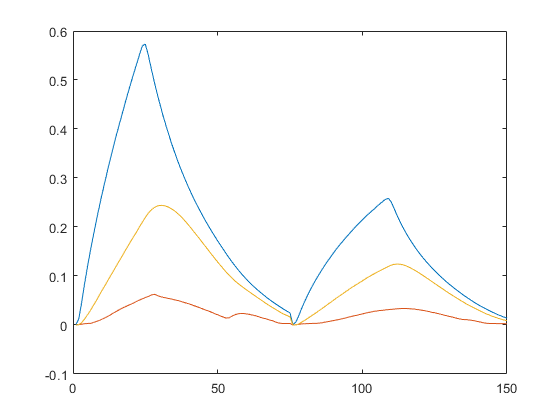

close all;
clear;
clc;
load data/threeTankParameter1.mat
load hyperparameter.mat

%load data/testData1.mat
load dataOut/testData10.mat
addpath(genpath('lib'),genpath('gpml-matlab-master'));

xD = [testData.x1,testData.x2,testData.x3];
plot(xD);

dxD = [testData.dx1,testData.dx2,testData.dx3];
%uD = [testData.u1 ,testData.u2];
uD = [testData.u1];
n = 3;
m = 3;

u1Full = uD(1,1);
%u2Half = uD(1,2);
u2Half = 0;
%u1Half = u1Full * 0.5;
%u1TQ = uD(1)* 0.75

parameter.u1 = u1Full;
parameter.u2 = 0 * u2Half;


% hyperparameterR1 = calcHyperparameter([xD(:,1)-xD(:,3),uD],dxD(:,1));
% hyperparameterR2 = calcHyperparameter([xD(:,3)-xD(:,2),xD(:,2)],dxD(:,2));
% hyperparameterR3 = calcHyperparameter([xD(:,1)-xD(:,3),xD(:,3)-xD(:,2)],dxD(:,3));

% hyperparameterR1 = calcHyperparameter([xD(:,1),xD(:,3),uD],dxD(:,1));
% hyperparameterR2 = calcHyperparameter([xD(:,2),xD(:,3)],dxD(:,2));
% hyperparameterR3 = calcHyperparameter([xD(:,1),xD(:,2),xD(:,3)],dxD(:,3));
%beta1 = [1; 2.4e-05*0.5];
beta1 = [1; 3e-05];
beta2 = [2e-05; -3e-05];
beta3 = [2.4e-05; 2.4e-05].*0.5;
for i = 1: length(xD)
    yD(i,1) = beta3(1) * h1([xD(i,:),uD(i,:)]) + beta3(2) * h2([xD(i,:),uD(i,:)]);         %!
end

% hyperparameter3 = calcHyperparameter([xD,uD],yD);                                          %!
% save hyperparameter.mat hyperparameter1 hyperparameter2 hyperparameter3

% hyperparameterR1 = calcHyperparameter([xD,uD],dxD(:,1));
% hyperparameterR2 = calcHyperparameter([xD,uD],dxD(:,2));
% hyperparameterR3 = calcHyperparameter([xD,uD],dxD(:,3));
% 
% hyperparameter1 = hyperparameterR1;
% hyperparameter2 = hyperparameterR2;
% hyperparameter3 =  hyperparameterR3;

sigmaX = [1e-7, 0, 0; 0, 1e-7, 0; 0, 0, 1e-7];
sigmaY = [5e-6, 0, 0; 0, 5e-6, 0; 0, 0, 5e-6];
%sigmaY = sigmaY(1,1);
kernelSE = {@squaredExponentialKernel, @squaredExponentialKernel, @squaredExponentialKernel};
meanFctTank = {@meanDx1,@meanDx2,@meanDx3};
meanFctZero = {@zeroMean,@zeroMean,@zeroMean};

 hyperparameter1.beta = beta1;
 hyperparameter2.beta = beta2;
 hyperparameter3.beta = beta3;
 hyperparameter1.B = [ 1e-07 , 0 ; 0 , 1e-04];
 hyperparameter2.B = [ 1e-04 , 0 ; 0 , 1e-04];
 hyperparameter3.B = [ 1e-04 , 0 ; 0 , 1e-04];
%   hyperparameter1.B = [ 1e-07 , 0 ; 0 , 1e-02];
%  hyperparameter2.B = [ 1e-02 , 0 ; 0 , 1e-02];
%  hyperparameter3.B = [ 1e-03 , 0 ; 0 , 1e-03];
% 
%  hyperparameter1.beta = [0; 0];
%  hyperparameter2.beta = [0; 0];
%  hyperparameter3.beta = [0; 0];


%hyperparameter1.sigmaN = hyperparameter1.sigmaN  + 1;
hyperparameterCell = {hyperparameter1, hyperparameter2, hyperparameter3};
%hyperTrans = {hyperparameterDx1, hyperparameterDx2, hyperparameterDx3};
%hyperDel = {hyperparameterDel1,hyperparameterDel2,hyperparameterDel3};
%hyperR = {hyperparameterR1,hyperparameterR2,hyperparameterR3};
hyperBasis = {hyperparameter1, hyperparameter2, hyperparameter3};


threeTank = WaterTank(3,3,sigmaX,sigmaY,parameter);

gP = DynamicSystemGP2(xD,uD,dxD,hyperBasis,kernelSE,meanFctTank,@measurement,sigmaX,sigmaY(1,1),1);

length = 300;
xGP = [0,0,0];
xGpEst = zeros(length,3);
dxGpEst = zeros(length,3);
sigma = zeros(length,3);
yGpEst = zeros(length,3);
x = zeros(length,3);
time = zeros(length,1);
xK = [0,0,0];
SigmaEst = sigmaX;

UKF = UnscentedKalmanFilter2(gP)

UKF =   UnscentedKalmanFilter2 with properties:

           s: 7
           n: 3
           m: 1
       gamma: 14.2478
    weightsM: [7×1 double]
    weightsC: [7×1 double]
      system: [1×1 DynamicSystemGP2]


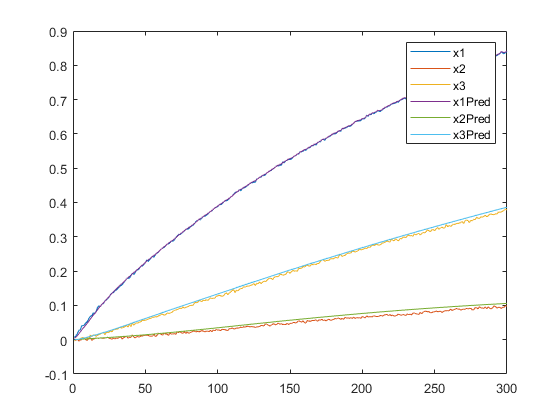

for i = 1 : length
    
    time(i) = i;
    xK = threeTank.stateTransition(xK,1);
    yK = threeTank.measurement(xK);
    x(i,:) = yK;
    
    tic
    [xGpEst(i,:),SigmaEst] = UKF.prediction(xGP,SigmaEst,yK(1),[parameter.u1],1);
    calcTime(i) = toc;
    
    xGP = xGpEst(i,:);
%     if x(i,1) > 0.5
%         parameter.u1 = 0;
%         parameter.u2 = 0;
%         threeTank.parameter = parameter;
%     end
%     if i == 300
%        pause 
%     end
end

plot(x)
hold on;
plot(xGpEst(:,1))
plot(xGpEst(:,2))
plot(xGpEst(:,3))
%plot (xD(:,1));
% plot (xD(1:180,2));
legend("x1","x2","x3","x1Pred","x2Pred","x3Pred")
hold off;

mean(calcTime)

ans = 0.0134

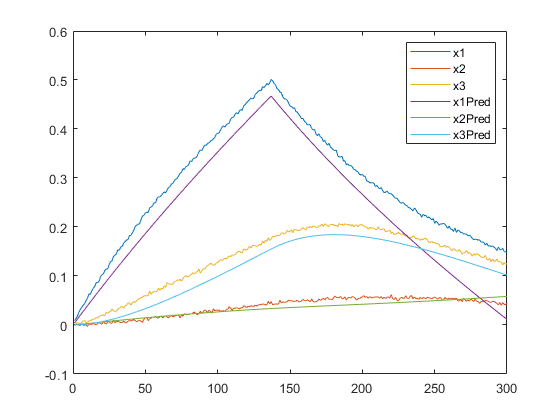

estimatedParam1 = UKF.system.transitionGP(1).hyperParameter;
estimatedParam2 = UKF.system.transitionGP(2).hyperParameter;
estimatedParam3 = UKF.system.transitionGP(3).hyperParameter;
threeTank.parameter.u1 = u1Full;
%length = 1;

% estimatedParam1.beta = [1; 2.5e-5];
% estimatedParam2.beta = [2.5e-5; 3.5e-5];
% estimatedParam3.beta = [2.5e-5; 2.5e-5];
xEst = [0,0,0];
xK = [0,0,0];
x = zeros(length,3);
xFullEst = zeros(length,3);
for i = 1: length
    time(i) = length;
    xK = threeTank.stateTransition(xK,1);
    yK = threeTank.measurement(xK);
    x(i,:) = yK;
    
    %dxEst = [meanDx1([xEst,threeTank.parameter.u1],estimatedParam1),meanDx2(xEst,estimatedParam2),meanDx3(xEst,estimatedParam3)];
    dxEst = [meanDx1R([xEst,threeTank.parameter.u1],estimatedParam1),meanDx2R([xEst,threeTank.parameter.u1],estimatedParam2),meanDx3R([xEst,threeTank.parameter.u1],estimatedParam3)];
    if x(i,1) > 0.5
        parameter.u1 = 0;
        parameter.u2 = 0;
        threeTank.parameter = parameter;
    end
    xEst = xEst + dxEst;
    xFullEst(i,:) = xEst;
end

plot(x)
hold on;
plot(xFullEst)
%plot (xD(:,1));
% plot (xD(1:180,2));
legend("x1","x2","x3","x1Pred","x2Pred","x3Pred")
hold off;

mean(calcTime)

ans = 0.0134

!PF is not working any more. could work with some redo


% xGP = [0,0,0];
% xGpEst = zeros(180,3);
% dxGpEst = zeros(180,3);
% sigma = zeros(180,3);
% yGpEst = zeros(180,3);
% x = zeros(180,3);
% time = zeros(180,1);
% xK = [0,0,0];
% pf = ParticleFilter(gP,10);
% for i = 1 : 180
%     %waterTank
%     time(i) = i;
%     xK = threeTank.stateTransition(xK,1);
%     yK = threeTank.measurement(xK);
%     x(i,:) = yK;
%     
%     %GP System
%     tic
%     xGpEst(i,:) = pf.prediction(yK,1);
%     calcTime(i) = toc;
%     
%     [xGP,dxGpEst(i,:),sigma] = gP.stateTransition(xGP,1);
%     sigma(i,:) = diag(sigma).';
%     
%     %xGpEst(i,:) = xGP;
%     %yGpEst(i,:) = gP.measurement(xGP);
% end
% plot(xGpEst);
% hold on;
% plot(x)
% %plot(yGpEst)
% hold off;
% plot(dxGpEst)
% 
% plot(calcTime)
% calcTimeM = mean(calcTime);
% 

% f1 = [dxGpEst(:,1)+2*sqrt(sigma(:,1)); flip(dxGpEst(:,1)-2*sqrt(sigma(:,1)),1)];
% f2 = [dxGpEst(:,2)+2*sqrt(sigma(:,2)); flip(dxGpEst(:,2)-2*sqrt(sigma(:,2)),1)];
% f3 = [dxGpEst(:,3)+2*sqrt(sigma(:,3)); flip(dxGpEst(:,3)-2*sqrt(sigma(:,3)),1)];
% 
% 
% fill([time; flip(time,1)], f1, [7 7 7]/8)
% hold on;
% fill([time; flip(time,1)], f2, [7 7 7]/8)
% fill([time; flip(time,1)], f3, [7 7 7]/8)
% plot(time, dxGpEst(:,1));
% plot(time, dxGpEst(:,2));
% plot(time, dxGpEst(:,3));
% 
% 
% legend('Varianz dx1','Varianz dx2','Varianz dx3', 'dx1 geschätzt', 'dx2 geschätzt', 'dx3 geschätzt');
% xlabel('Zeit t /s')
% ylabel('Fuellstand /m')
% hold off;

function hyperparameter = calcHyperparameter(xD,yD)

n = size(xD,2);
m = size(yD,2);

for i = 1 : n
    xStd(1,i) = std(xD(:,i));
    xMean(1,i) = mean(xD(:,i));

end
for i = 1 : m
    yStd(1,i) = std(yD(:,i));
    yMean(1,i) = mean(yD(:,i));
end

xDnorm = (xD - xMean)./ xStd;
yDnorm = (yD - yMean)./ yStd;
% 
% xDnorm(:,4) = xDnorm(:,4) .* 2;
% xDnorm(:,1) = xDnorm(:,1) .* 2;

meanfunc = [];                    % empty: don't use a mean function
covfunc = @covSEiso;              % Squared Exponental covariance function
likfunc = @likGauss;              % Gaussian likelihood
sigF = 1;
sigN = 1E-6 / yStd / yStd;
l = 1;
hyp = struct('mean', [], 'cov', [log(sigF) log(l)], 'lik', log(sigN));
hyp2 = minimize(hyp, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, xDnorm, yDnorm);

hyperparameter.l = exp(hyp2.cov(1)); %length scale
hyperparameter.sigmaF = exp(hyp2.cov(2)); %signal std Dev sigmaF
hyperparameter.sigmaN = exp(hyp2.lik(1)); %noise std dev sigmaN
end

function y = measurement(x,sigmaY,m)
    y = x(1,1) + randn(1,m) * sigmaY;
end

function y = measurementFull(x,sigmaY,m)
    y = x + randn(1,m) * sigmaY;
end